# Get Galaxy Profiles

## Stellar constats


c = 299792.458; % Speed of light in vacuum (Km/s)
% The positive charge RMS anomality of nucleons
B_sigma = 0.0000000061576779354155376441072376072967;

% The Star parameters
A_Sigma_star = 0.000000000000004495594326077030347123131497606; % The abnormality of Star


sig_stars = 0.945*15000;
sig_H = 103;

% The Gas parameters
A_Sigma_H = 0.99e-10; % The electron-proton anomality of GAS

% Estimation parameters

resolution=200;
nloops = 14;


## Test of M31 data

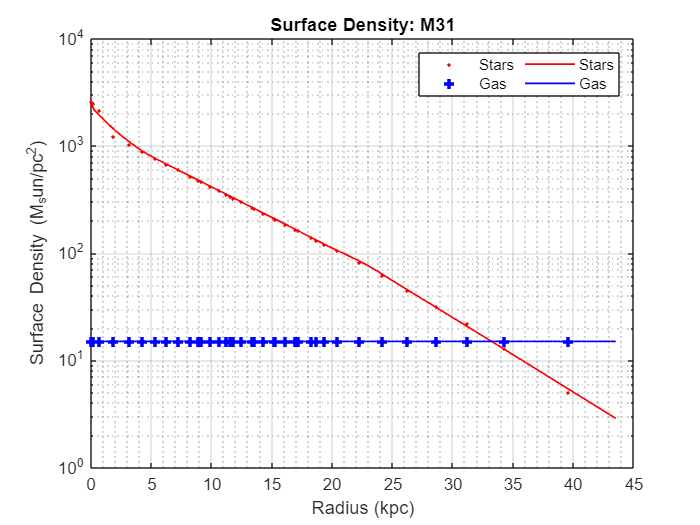

GalaxyName='M31';

VelMassData = [
    0.22	163.24	15.61	15	2500;
0.65	210.95	18.56	15	2124;
1.86	223.8	10.72	15	1224;
3.19	226.79	7.96	15	1021;
4.23	213.74	8.17	15	888;
5.32	212.54	7.55	15	767;
6.27	221.94	7.2	15	676;
7.2	223.3	8.49	15	597;
8.2	225.97	9.28	15	523;
8.88	233.09	32.4	15	478;
9.14	226.63	9.07	15	463;
9.93	223.45	10.29	15	417;
10.62	221.25	10.24	15	381;
11.25	221.17	11.16	15	351;
11.55	217.54	35.26	15	338;
11.83	213.58	9.75	15	326;
12.48	215.04	12.67	15	300;
13.37	215.12	12.82	15	266;
13.55	230.53	35.63	15	260;
14.29	217.92	13.52	15	236;
15.2	215.97	13.09	15	209;
15.25	212.91	36.6	15	208;
16.08	223.22	13.07	15	186;
16.91	212.36	36.67	15	167;
17.21	213.32	13.44	15	161;
18.31	213.85	15.37	15	139;
18.68	204.64	38.1	15	132;
19.38	199.73	15.19	15	121;
20.41	220.27	37.18	15	105;
22.26	213.35	37.17	15	81;
24.12	219.28	36.73	15	62;
26.26	217.99	35.88	15	45;
28.63	222.84	38.16	15	32;
31.23	204.28	37.89	15	22;
34.28	210.33	38.76	15	13;
39.56	221.84	36.68	15	5;
];

figure(1)
[r_data,V_obs,V_err,R_kpc,r_model,V_model,SigmaS,SigmaG,MStars,Mgas] = SRotation_curves(VelMassData,GalaxyName);

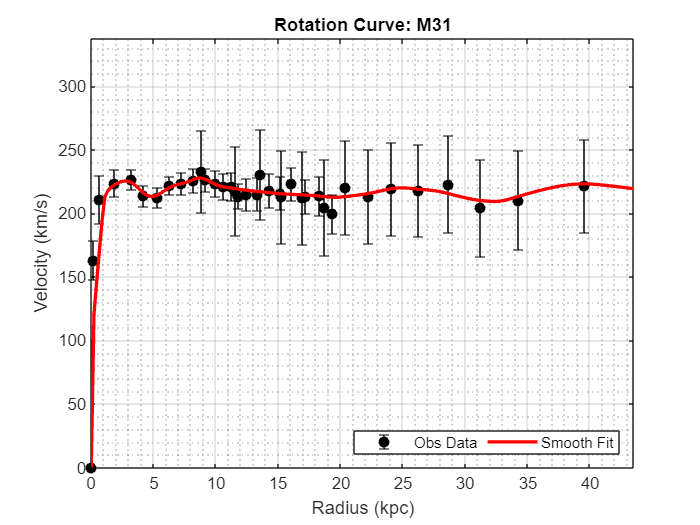


figure(2);
errorbar(r_data, V_obs, V_err, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Obs Data');
hold on;
plot(r_model, V_model, 'r-', 'LineWidth', 2, 'DisplayName', 'Smooth Fit');
xlabel('Radius (kpc)');
ylabel('Velocity (km/s)');
titles = append('Rotation Curve: ',GalaxyName);
title(titles);
legend('Location', 'southeast','NumColumns',2);
grid on;
grid minor;
xlim([0, max(r_model)]);
ylim([0, max(V_obs+3*V_err)]); % Enforce physical limits
hold off

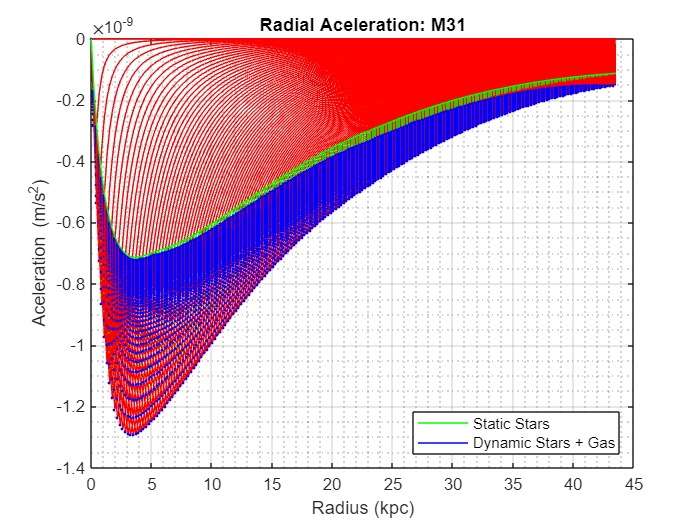

figure(3)
[V_tot,V_MOND,V_ele_G,V_ele,Zdist,StarProfile,GasZprofile,ax,ay] = fit_rotation_curveG(B_sigma,A_Sigma_star,A_Sigma_H,r_model,V_model,MStars,Mgas,sig_stars,sig_H,resolution,0,GalaxyName);

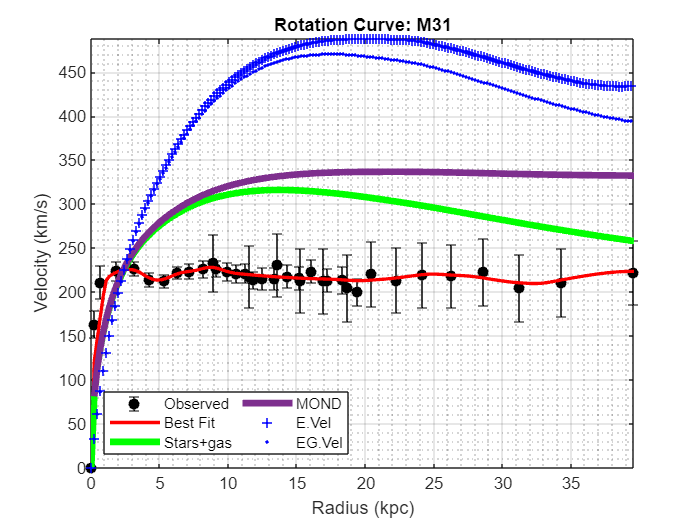

figure(4)
plotVelocities_SG(r_data,V_obs,V_err,r_model,V_model,V_tot,V_MOND,V_ele,V_ele_G,GalaxyName);

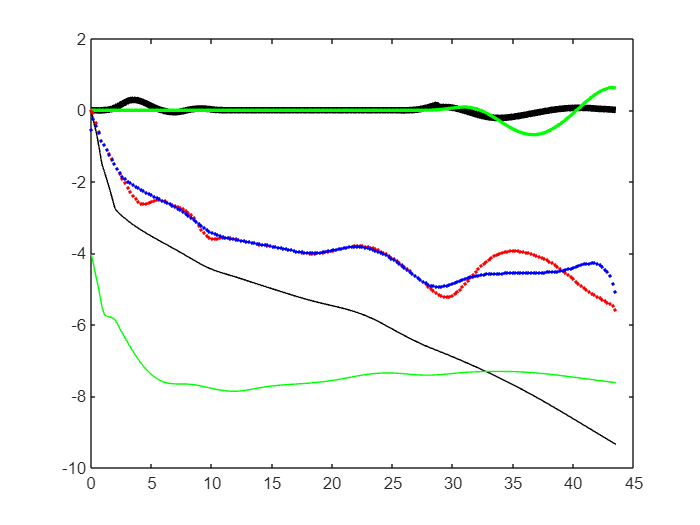

NSigma_S = MStars;
NSigma_H = Mgas;
NV_ele = V_ele;
testwhere=[];
for lps = 1:nloops
    ggain = 1.0-0.25*(mod(lps,3)>0) + 0.25*(mod(lps,3)==0);
    [Sigma_obs,Sigma_est,NSigma_S,NSigma_H,error,errorH,testwhere] = getNewDensities(r_model,V_model,NV_ele,NSigma_S,NSigma_H,0.35,2.0*(lps>1),ggain,testwhere);

    figure(5)
    plot(r_model,5*error,"k-",'LineWidth', 4)
    hold on
    plot(r_model,5*errorH,"g-",'LineWidth', 2)
    plot(r_model,log(NSigma_S/max(NSigma_S)),"k-")
    plot(r_model,log(NSigma_H/max(NSigma_S)),"g-")
    plot(r_model,log(Sigma_obs/max(Sigma_obs)),"r.")
    plot(r_model,log(Sigma_est/max(Sigma_obs)),"b.")
    hold off

    figure(6)
    [V_tot,V_MOND,NV_ele_G,NV_ele,Zdist,StarProfile,GasZprofile,ax,ay] = fit_rotation_curveG(B_sigma,A_Sigma_star,A_Sigma_H,r_model,V_model,NSigma_S,NSigma_H,sig_stars,sig_H,resolution,lps,GalaxyName);

end

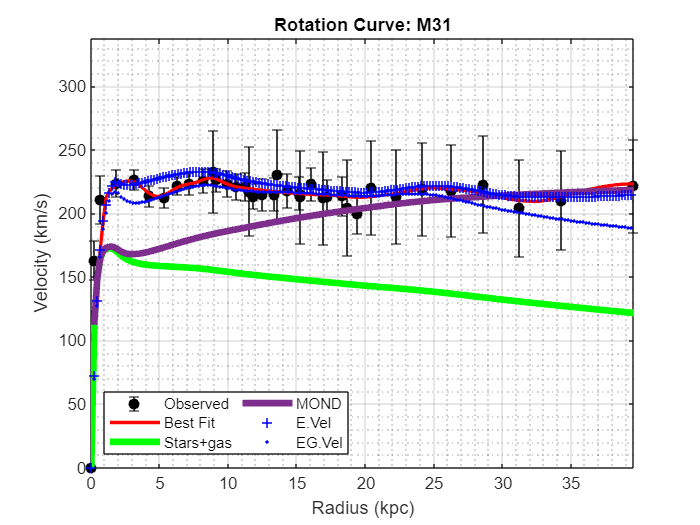

figure(7)
    plotVelocities_SG(r_data,V_obs,V_err,r_model,V_model,V_tot,V_MOND,NV_ele,NV_ele_G,GalaxyName);

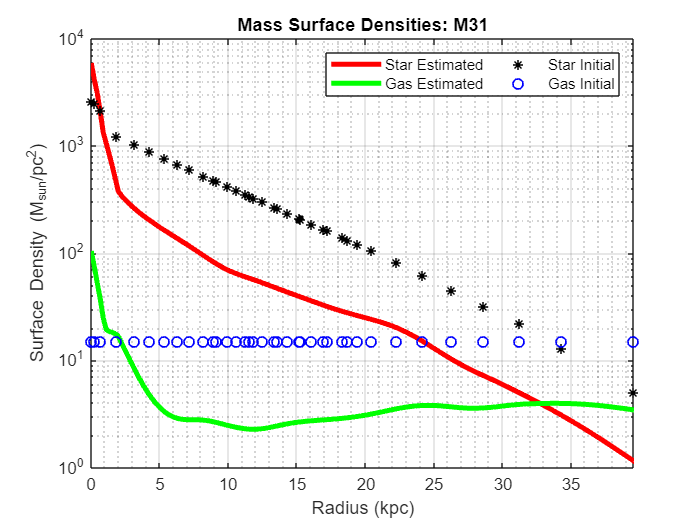

figure(8)
semilogy(r_model,NSigma_S,"r-", 'LineWidth', 3, 'DisplayName', 'Star Estimated')
hold on
semilogy(r_model,NSigma_H,"g-", 'LineWidth', 3, 'DisplayName', 'Gas Estimated')
semilogy(R_kpc,SigmaS,"k*", 'LineWidth', 1, 'DisplayName', 'Star Initial')
semilogy(R_kpc,SigmaG,"bo", 'LineWidth', 1, 'DisplayName', 'Gas Initial')
xlabel('Radius (kpc)');
ylabel('Surface Density (M_{sun}/pc^2)');
titles = append('Mass Surface Densities: ',GalaxyName);
title(titles);
legend('Location', 'northeast','NumColumns',2);
xlim([0, max(r_data)]);
grid on;
grid minor;
hold off


mascts = (1000^2)*2*pi*(r_model(3)-r_model(2));
totEstMASS = mascts*sum(MStars.*r_model)

totEstMASS = 5.4130e+11

totEstMASS2 = mascts*sum(NSigma_S.*r_model)

totEstMASS2 = 1.1924e+11

totEstMASS2/totEstMASS

ans = 0.2203

totEstGas = mascts*sum(NSigma_H.*r_model)

totEstGas = 2.0902e+10

TotGalMass = totEstMASS2+totEstGas

TotGalMass = 1.4014e+11

totObsEstRatioGas= sum(NSigma_H.*r_model)/sum(Mgas.*r_model)

totObsEstRatioGas = 0.2331

save("Andromedab_103_200.mat");